# MAS416 - Tutorial 7

## Problem 2

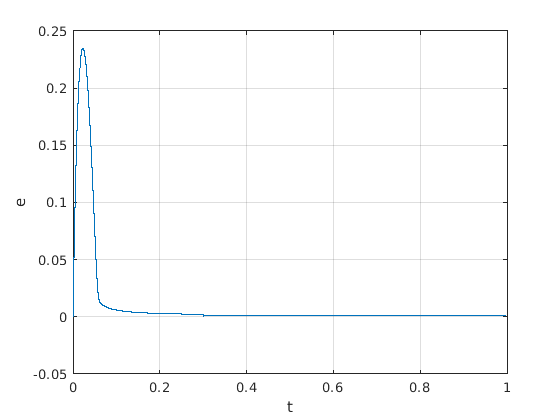

clc; clear all; close all;

% Constant resistance
R1 = 200; % Ohm
R3 = R1; %  Ohm

% Variable resistance
R2_min = 0; % Ohm
R2_max = 10*10^3; % Ohm

% Capacitance
C1 = 60*10^-6; % uF
C2 = 2*10^-6; % uF

Us_max = 12; % V

UC1 = 0; % V
UC2 = 0; % V

t = 0; % s
dt = 10^-6; % s
simTime = 1; % s
idx = 1; % Counter

tr = 0.3; % s, ramp time for Us

Kp = 50000;
tau_i = 2;
u_err = 0;
u_err_int = 0;

while(t <= simTime)
    % Calculations
    R2 = Kp * u_err + Kp/tau_i * u_err_int;
    % Saturate R2
    if(R2 >= R2_max)
        R2 = R2_max;
    elseif(R2 <= R2_min)
        R2 = R2_min;
    end

    % Ramp Us
    if(t <= tr)
        Us = t/tr * Us_max;
    else
        Us = Us_max;
    end

    % Voltage error, UC1 ref is always 60% of Us:
    u_err = 0.6*Us-UC1;

    % Calculate currents in the system
    % Current through R1
    i1 = (Us-UC2)/R1;
    % Current through R3:
    i3 = (UC2-UC1)/R3;
    % Current through R2 (with condition for R2 to be greater than 0)
    if(R2 > 0)
        i2 = UC2/R2;
    else
        i2 = 0;
    end
    % Using Kirchoffs law to find i4:
    i4 = i1 - i3 - i2;

    % Set up state variables with the calculated currents
    UC1Dot = 1/C1 * i3;
    UC2Dot = 1/C2 * i4;

    % Logging
    t_plt(idx) = t;
    u_err_plt(idx) = u_err;
    %us_plt(idx) = Us;

    % Time integration
    UC1 = UC1 + UC1Dot * dt;
    UC2 = UC2 + UC2Dot * dt;
    u_err_int = u_err_int + u_err * dt;

    % Updating variables
    t = t + dt;
    idx = idx + 1;
end

% Ramp verification plot
%plot(t_plt, us_plt)

% Voltage error plot
plot(t_plt, u_err_plt)
grid
xlabel("t")
ylabel("e")